## Constants

pump_power = 1000; %[W]
pump_time = 3600*12; %[s]
pool_area = 3*8; %[m^2]

operationele_uren = 11; % [h]
nacht_uren = 24- operationele_uren;
weekend_uren = 63;

volume = pool_area*1.6;
rho = 1000;
cpw = 4186;

alpha = 5.8; %[W/m^2K] heat transfer coeff
cpa = 1005; % [kg/JK] specific heat coeff
epsilon=0.9; % white paint 
epsilon_mat = 0.9 % blue polyethylene

epsilon_mat = 0.9000

sigma= 5.67* 10^(-8) % stefan

sigma = 5.6700e-08


pump_energy = pump_power*pump_time*2.77777778 * 10^(-7); %[kWh]

## Stationair

#### Berekening damp fractie

% Ruimte
temp_ruimte = 23;
psat_ruimte = calculatePressure(temp_ruimte);
phi_ruimte = 0.65;
p=10^5;
x_ruimte = 0.622*phi_ruimte*psat_ruimte/(p-phi_ruimte*psat_ruimte)

x_ruimte = 0.0118


% Water
temp_water = 34;
psat_water = calculatePressure(temp_water);
phi_water = 1;
x_water = 0.622*phi_water*psat_water/(p-phi_water*psat_water)

x_water = 0.0362

#### Massatransport

m = alpha*pool_area/cpa*(x_water-x_ruimte) % [kg/s]

m = 0.0034

#### Warmtetransport

Latent

L = 2267000; % [J/kg] Latent heat evaporation
Q_latent = m*L

Q_latent = 7.6809e+03

Convectie

Q_convection = alpha *pool_area  *  (temp_water-temp_ruimte)

Q_convection = 1.5312e+03

Straling

Q_straling = pool_area*epsilon*sigma*((temp_water+273)^4- (temp_ruimte+273)^4)

Q_straling = 1.4774e+03

Input

Q_in = Q_straling+Q_convection+Q_latent

Q_in = 1.0690e+04

#### Verbruik

verbruik_stationair = Q_in* 10^(-3) * operationele_uren % [kWh]

verbruik_stationair = 117.5848

kosten_stationair = verbruik_stationair * 0.13 * 350

kosten_stationair = 5.3501e+03

## Nacht

#### Verwarming aan 's nachts

Q_nacht_straling = pool_area*epsilon_mat*sigma*((temp_water+273)^4- (temp_ruimte+273)^4)

Q_nacht_straling = 1.4774e+03

Q_nacht_convection = alpha *pool_area  *  (temp_water-temp_ruimte)

Q_nacht_convection = 1.5312e+03

Q_nacht_latent = Q_latent * 0.02

Q_nacht_latent = 153.6188

Q_nacht_out = Q_nacht_straling+Q_nacht_convection + Q_nacht_latent

Q_nacht_out = 3.1622e+03

#### Verwarming uit 's nachts

Q_nacht_straling2

#### Verbruik

verbruik_nacht = Q_nacht_out * 10^(-3) * nacht_uren % [kWh]

verbruik_nacht = 41.1087

## Weekend

verbruik_weekend_estimate = Q_nacht_out * 10^(-3) * weekend_uren % [kWh]

verbruik_weekend_estimate = 199.2193

factor_weekend = 0.01;
Q_in_weekend =  factor_weekend * 1 * 10^3;
f = @(t,T) (Q_in_weekend-alpha * pool_area  *  ((T-273)-temp_ruimte) - pool_area*epsilon_mat*sigma*((T)^4- (temp_ruimte+273)^4))/(rho*volume*cp) 

f = function_handle with value:
    @(t,T)(Q_in_weekend-alpha*pool_area*((T-273)-temp_ruimte)-pool_area*epsilon_mat*sigma*((T)^4-(temp_ruimte+273)^4))/(rho*volume*cp)


tspan = [0 3600 * weekend_uren];
T0 = 34+273;
[t,T] = ode45(f, tspan, T0);

Q_vector = alpha * pool_area  *  ((T-273)-temp_ruimte) + pool_area*epsilon_mat*sigma*((T).^4- (temp_ruimte+273)^4);
verbruik_weekend = sum(Q_vector*10^(-3)*(t(2)-t(1))/3600) %[kWh]

verbruik_weekend = 96.9513

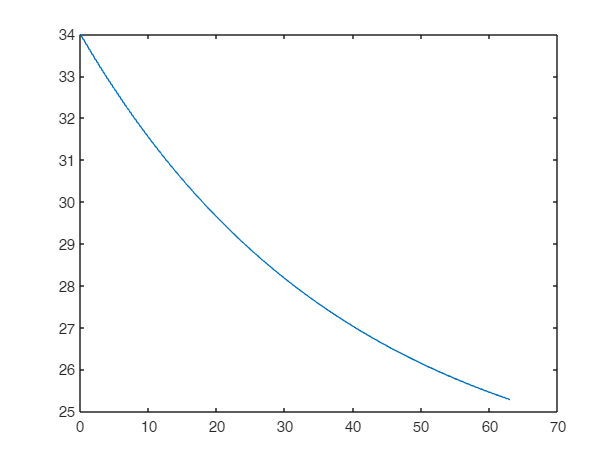

plot(t/3600, T-273)

## Opstart

Q_opstart_in = 25*10^3;

f_opstart = @(t_opstart,T_opstart) (Q_opstart_in - alpha * pool_area  *  ((T_opstart-273)-temp_ruimte) - pool_area*epsilon_mat*sigma*((T_opstart)^4- (temp_ruimte+273)^4))/(rho*volume*cp); 
tspan_opstart = [0 3600 * 5];
T0_opstart = T(end);
[t_opstart,T_opstart] = ode45(f_opstart, tspan_opstart, T0_opstart);

idx = interp1(T_opstart, 1:length(T_opstart), 34+273, 'nearest');

kost_opstart = Q_opstart_in  *10^(-3) * t_opstart(idx)/3600 *0.13

kost_opstart = 13

totaal_kost_opstart = kost_opstart + weekend_uren*Q_in_weekend*10^(-3)*0.13

totaal_kost_opstart = 13.0819

kost_opstart_alternatief = Q_nacht_out * 10^(-3) * weekend_uren * 0.13

kost_opstart_alternatief = 25.8985

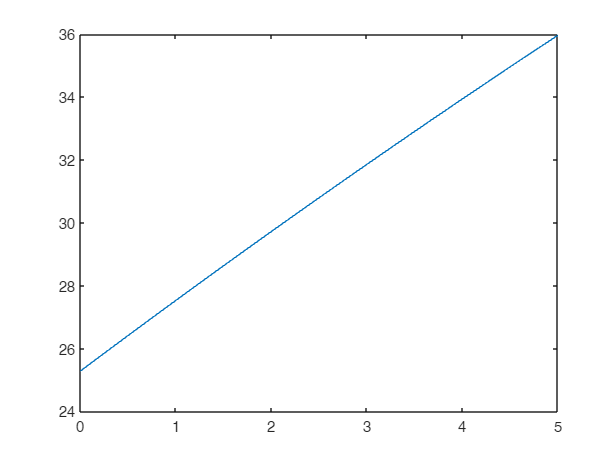

plot(t_opstart/3600, T_opstart-273)